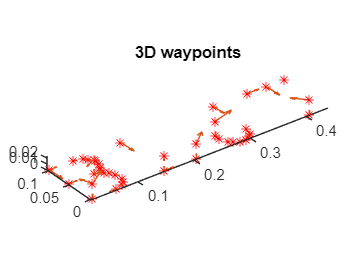


load hershey
letter_1 = hershey{'B'};
letter_2 = hershey{'L'};
letter_3 = hershey{'J'};
letter_4 = hershey{'T'};
scale = 0.12;
moving_up = 0.2*scale;

% ----------------------------
% Build raw strokes (x,y) + add z=0
% ----------------------------
p1 = [scale*letter_1.stroke; zeros(1,size(letter_1.stroke,2))];
p2 = [scale*letter_2.stroke; zeros(1,size(letter_2.stroke,2))];
p3 = [scale*letter_3.stroke; zeros(1,size(letter_3.stroke,2))];
p4 = [scale*letter_4.stroke; zeros(1,size(letter_4.stroke,2))];

% ----------------------------
% FIX NaN breaks (pen-up moves)
% If NaN appears in x (or y), copy previous x,y and set z = moving_up
% (handles multiple NaNs safely)
% ----------------------------
p1 = fixPenUpNaN(p1, moving_up);
p2 = fixPenUpNaN(p2, moving_up);
p3 = fixPenUpNaN(p3, moving_up);
p4 = fixPenUpNaN(p4, moving_up);

% ----------------------------
% Shift letters left-to-right (cumulative!)
% ----------------------------
% ---- Auto spacing based on real letter widths ----
gap = 0.5*scale; % your chosen gap

% helper: width of a letter (ignore pen-up NaNs already fixed)
w1 = max(p1(1,:)) - min(p1(1,:));
w2 = max(p2(1,:)) - min(p2(1,:));
w3 = max(p3(1,:)) - min(p3(1,:));

% align letter starts and shift cumulatively
x1_start = min(p1(1,:));
x2_start = min(p2(1,:));
x3_start = min(p3(1,:));
x4_start = min(p4(1,:));

shift2 = (x1_start + w1 + gap) - x2_start;
p2(1,:) = p2(1,:) + shift2;

shift3 = (min(p2(1,:)) + w2 + gap) - x3_start;
p3(1,:) = p3(1,:) + shift3;

shift4 = (min(p3(1,:)) + w3 + gap) - x4_start;
p4(1,:) = p4(1,:) + shift4;

% ----------------------------
% Create intermediate via points between letters (pen up then down)
% ----------------------------
p_middle  = [[p1(1,end) p1(2,end) moving_up]; [p2(1,1) p2(2,1) 0]]';
p_middle2 = [[p2(1,end) p2(2,end) moving_up]; [p3(1,1) p3(2,1) 0]]';
p_middle3 = [[p3(1,end) p3(2,end) moving_up]; [p4(1,1) p4(2,1) 0]]';

% ----------------------------
% Concatenate ALL waypoints into one p
% ----------------------------
p = [p1 p_middle p2 p_middle2 p3 p_middle3 p4];

% ----------------------------
% Plot waypoint path in 3D
% ----------------------------
figure
plot3(p(1,:),p(2,:),p(3,:),"*r");
hold on
quiver3(p(1,1:(end-1)),p(2,1:(end-1)),p(3,1:(end-1)),diff(p(1,:)),diff(p(2,:)),diff(p(3,:)))
axis equal
title("3D waypoints")

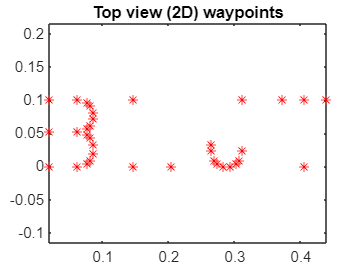


% ----------------------------
% Top view of waypoints (2D from beginning)
% ----------------------------
figure
plot(p(1,:), p(2,:), "*r")
axis equal
title("Top view (2D) waypoints")

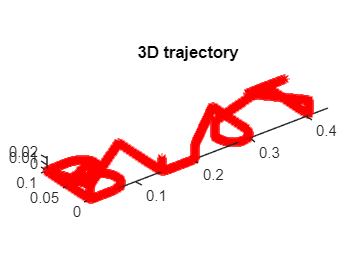


% ----------------------------
% Generate the trajectory
% ----------------------------
dt = 0.01;
axis_speed_limit = 0.5*scale;
acceleration_time = 0.2;

traj = mstraj(p(:,1:end)', ...
    [axis_speed_limit axis_speed_limit axis_speed_limit], ...
    [], p(:,1)', dt, acceleration_time);

figure
plot3(traj(:,1),traj(:,2),traj(:,3),"*r")
axis equal
title("3D trajectory")

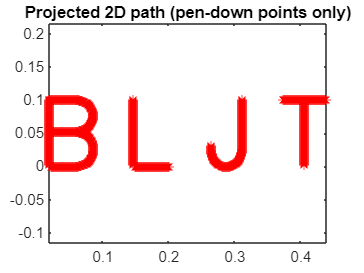


% ----------------------------
% Filter pen-down points for 2D plot (z ~ 0)
% ----------------------------
filtered_2D_point = [];
index = 1;
for i = 1:1:length(traj)
    if (traj(i,3) < 0.0001)
        filtered_2D_point(index,1) = traj(i,1);
        filtered_2D_point(index,2) = traj(i,2);
        index = index + 1;
    end
end

figure
plot(filtered_2D_point(:,1),filtered_2D_point(:,2),"*r")
axis equal
title("Projected 2D path (pen-down points only)")


% ----------------------------
% Offset so that when joints are in zero position
% the EF is at the start point of the trajectory
% ----------------------------
X_offset = traj(1,1) - 0.1467438;
Y_offset = traj(1,2) - 0;
Z_offset = traj(1,3) - 0.038205;

traj_offset = traj;
traj_offset(:,1) = traj_offset(:,1) - X_offset;
traj_offset(:,2) = traj_offset(:,2) - Y_offset;
traj_offset(:,3) = traj_offset(:,3) - Z_offset;

% create the input data for simulink
time = 0:dt:(dt*(length(traj_offset)-1));
trajectory_time = [time' traj_offset];

% ----------------------------
% Reduce the resolution for trajectory display
% ----------------------------
theshold_filter_m = 0.001;
traj_offset_display(1,1) = traj_offset(1,1);
traj_offset_display(1,2) = traj_offset(1,2);
traj_offset_display(1,3) = traj_offset(1,3);
idx = 1;

for i=2:1:length(traj_offset)
    if ((abs(traj_offset(i,1)-traj_offset_display(idx,1)) > theshold_filter_m) || ...
        (abs(traj_offset(i,2)-traj_offset_display(idx,2)) > theshold_filter_m) || ...
        (abs(traj_offset(i,3)-traj_offset_display(idx,3)) > theshold_filter_m))

        idx = idx + 1;
        traj_offset_display(idx,1) = traj_offset(i,1);
        traj_offset_display(idx,2) = traj_offset(i,2);
        traj_offset_display(idx,3) = traj_offset(i,3);
    end
end

% ----------------------------
% Local function to fix NaN pen-up points
% ----------------------------
function P = fixPenUpNaN(P, moving_up)
k = find(isnan(P(1,:)) | isnan(P(2,:)));
for ii = 1:length(k)
    idx = k(ii);
    if idx == 1
        % If the first point is NaN, just set to 0 and lift pen
        P(1,idx) = 0;
        P(2,idx) = 0;
        P(3,idx) = moving_up;
    else
        % Copy previous x,y and lift pen
        P(1,idx) = P(1,idx-1);
        P(2,idx) = P(2,idx-1);
        P(3,idx) = moving_up;
    end
end
end
